# 034IN "Fundamentals of Automatic Control" - Introduction to MATLAB  Part 6 - LTI Systems 

This is the sixth MATLAB live script of the collection 034IN "Fundamentals of Automatic Control" - Introduction to MATLAB, devoted to introducing the MATLAB environment and tools for solving practical problems related to the topics of the 034IN course, i.e., performance analysis of dynamic systems, design of control law for continuous-time linear dynamical systems, approximate discretization of a continuous-time control law, etc.

Use [this link](matlab:open('./usingMATLAB_034IN.mlx')) to go back to the main live script of the collection.

##  Objectives

 The aim of this module is to understand how to create and manipulate **LTI systems** in MATLAB. 

## Time Invariant Linear Dynamic Systems

AN LTI system can be described

- using a state-space description

- using the transfer function matrix for a MIMO system or a single transfer function for a SISO system

In MATLAB, it is possible to define a linear time-invariant dynamical system as an object of type `numLTI model` from any of these descriptions (use `help` `numlti` for details ). Using these MATLAB objects, it is possible to analyze the properties of the corresponding dynamic system, and also to simulate the evolution of the dynamic system over time with assigned initial conditions and inputs.

From now on, for simplicity, we only consider SISO systems.

### LTI-System Object from the State-Space Description

Starting from the state equation, you can

- define the matrices A, B, C, D of the state equations in the MATLAB workspace;

- define the LTI system by means of the command `ss`

help ss

 ss  State-space models.
 
   Construction:
     SYS = ss(A,B,C,D) creates an object SYS representing the continuous- 
     time state-space model
          dx/dt = Ax(t) + Bu(t)
           y(t) = Cx(t) + Du(t)
     You can set D=0 to mean the zero matrix of appropriate size. SYS is 
     of type ss when A,B,C,D are dense numeric arrays, of type GENSS when 
     A,B,C,D depend on tunable parameters (see REALP and GENMAT), and 
     of type USS when A,B,C,D are uncertain matrices (requires Robust 
     Control Toolbox). Use SPARSS when A,B,C,D are sparse matrices.
 
     SYS = ss(A,B,C,D,Ts) creates a discrete-time state-space model with
     sample time Ts (set Ts=-1 if the sample time is undetermined).
 
     SYS = ss(D) specifies a static gain matrix D.
 
     You can set additional model properties by using name/value pairs.
     For example,
        sys = ss(-1,2,1,0,'InputDelay',0.7,'StateName','p

#### A few Examples

Given the following state-space description of a continuous-time dynamical system


$$\left\{
\begin{array}{lcl}
\dot{x}_1(t)&=& -x_2(t)+3 u(t)\\
\dot{x}_2(t)&=& -3 x_1(t)+2 x_2(t)\\
y(t)&=& 4 x_1(t)+2 u(t)
\end{array}
\right.$$


the corresponding MATLAB object is given by

clear

A = [0 -1;-3 2]; B = [3;0]; C=[4 0]; D=2; % the system matrices
sysC = ss(A, B, C, D) %#ok<NASGU> % the LTI system

sysC =
 
  A = 
       x1  x2
   x1   0  -1
   x2  -3   2
 
  B = 
       u1
   x1   3
   x2   0
 
  C = 
       x1  x2
   y1   4   0
 
  D = 
       u1
   y1   2
 
Continuous-time state-space model.
Model Properties


Consider a continuous-time dynamical system, described by the model


$$\left\{
\begin{array}{lcl}
\dot{x}_1(t)&=& x_2(t)\\
\dot{x}_2(t)&=&  x_3(t)\\
\dot{x}_3(t) &=& x_1(t)-2x_2(t)+3x_3(t)+6 u(t)\\
y(t)&=&  x_1(t)
\end{array}
\right.$$


then

A = [0 +1 0;0  0  +1; 1  -2 +3]; B = [0; 0; 6]; C=[1  0  0]; D=0; % the system matrices
sysC_2 = ss(A, B, C, D) %#ok<NASGU> % the LTI system

sysC_2 =
 
  A = 
       x1  x2  x3
   x1   0   1   0
   x2   0   0   1
   x3   1  -2   3
 
  B = 
       u1
   x1   0
   x2   0
   x3   6
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


### LTI-System Object from the Transfer Function 

Given a transfer function as model for an LTI system, you can create an LTImodel object by using the `tf` or the `zpk` command:

help tf

 tf  Construct transfer function or convert to transfer function.
 
   Construction:
     SYS = tf(NUM,DEN) creates a continuous-time transfer function SYS with
     numerator NUM and denominator DEN. SYS is an object of type tf when
     NUM,DEN are numeric arrays, of type GENSS when NUM,DEN depend on tunable
     parameters (see REALP and GENMAT), and of type USS when NUM,DEN are
     uncertain (requires Robust Control Toolbox).
 
     SYS = tf(NUM,DEN,TS) creates a discrete-time transfer function with
     sample time TS (set TS=-1 if the sample time is undetermined).
 
     S = tf('s') specifies the transfer function H(s) = s (Laplace variable).
     Z = tf('z',TS) specifies H(z) = z with sample time TS.
     You can then specify transfer functions directly as expressions in S
     or Z, for example,
        s = tf('s');  H = exp(-s)*(s+1)/(s^2+3*s+1)
 
     SYS = tf

help zpk

 zpk  Constructs zero-pole-gain model or converts to zero-pole-gain format.
 
   Construction:
     SYS = zpk(Z,P,K) creates a continuous-time zero-pole-gain (zpk) model 
     SYS with zeros Z, poles P, and gains K. SYS is an object of class @zpk.
 
     SYS = zpk(Z,P,K,Ts) creates a discrete-time zpk model with sampling
     time Ts (set Ts=-1 if the sample time is undetermined).
 
     S = zpk('s') specifies H(s) = s (Laplace variable).
     Z = zpk('z',TS) specifies H(z) = z with sample time TS.
     You can then specify zpk models directly as expressions in S or Z, 
     for example,
        z = zpk('z',0.1);  H = (z+.1)*(z+.2)/(z^2+.6*z+.09)
 
     SYS = zpk creates an empty zero-pole-gain model.
     SYS = zpk(D) specifies a static gain matrix D.
 
     You can set additional model properties by using name/value 

#### Example

Consider the LTI systems


$$G_1(s) = \displaystyle \frac{s+1}{s^2+3s+16} \qquad \qquad G_2(s) = 4\,\displaystyle \frac{(s+1.0)\,(s+0.4)}{s\,(s+8)}$$


then 

numG1 = [ 1 1 ]; denG1 = [ 1 3 16 ];  % coeffs of the polynomials N(s) and D(s)
G1 = tf(numG1, denG1)

G1 =
 
      s + 1
  --------------
  s^2 + 3 s + 16
 
Continuous-time transfer function.
Model Properties



Zset = [-1.0  -0.4]; % the zeros
Pset = [0  -8];      % the poles
Kval = 4;            % the gain coeff.
G2 = zpk(Zset, Pset, Kval)

G2 =
 
  4 (s+1) (s+0.4)
  ---------------
      s (s+8)
 
Continuous-time zero/pole/gain model.
Model Properties


#### Alternative Way of Using the tf Command

Continuous-time and discrete-time ''elementary'' transfer functions can be defined, and used as ''building blocks'' in writing the expressions of the actual transfer functions.

Consider


$$G_1(s) = e^{-s}\, \displaystyle \frac{s+1}{s^2+3s+16}$$


s=tf('s');
Gs = exp(-2*s) * (s+1)/(s^2+3*s+2)

Gs =
 
                  s + 1
  exp(-2*s) * -------------
              s^2 + 3 s + 2
 
Continuous-time transfer function.
Model Properties


## Simulation of LTI Systems

The following MATLAB commands are available, both for continuos-time and discrete-time LTI system:

- `step`: simulation of the step response;

- `initial`: simulation of the free state and output movements;

- `lsim`: simulation of the forced movements.

### Example: Forced Output Movement of a Continuous-Time System

Consider the system 


$$\left\{
\begin{array}{lcl}
\dot{x}_1(t)&=& -x_1(t)+3 u(t)\\
\dot{x}_2(t)&=& -3 x_1(t)-2 x_2(t)\\
y(t)&=& 4 x_1(t)+2 u(t)
\end{array}
\right.$$


Let's calculate the forced state and output trajectories corresponding to the input 


$$u(t) = \big[3+2\,\sin\left(4 \pi\,t\right) \big] \cdot 1(t)$$


clear

A = [-1 0;-3 -2]; B = [3;0]; C = [4 0]; D = 2; % the system matrices
sysC = ss(A, B, C, D) % the LTI system

sysC =
 
  A = 
       x1  x2
   x1  -1   0
   x2  -3  -2
 
  B = 
       u1
   x1   3
   x2   0
 
  C = 
       x1  x2
   y1   4   0
 
  D = 
       u1
   y1   2
 
Continuous-time state-space model.
Model Properties


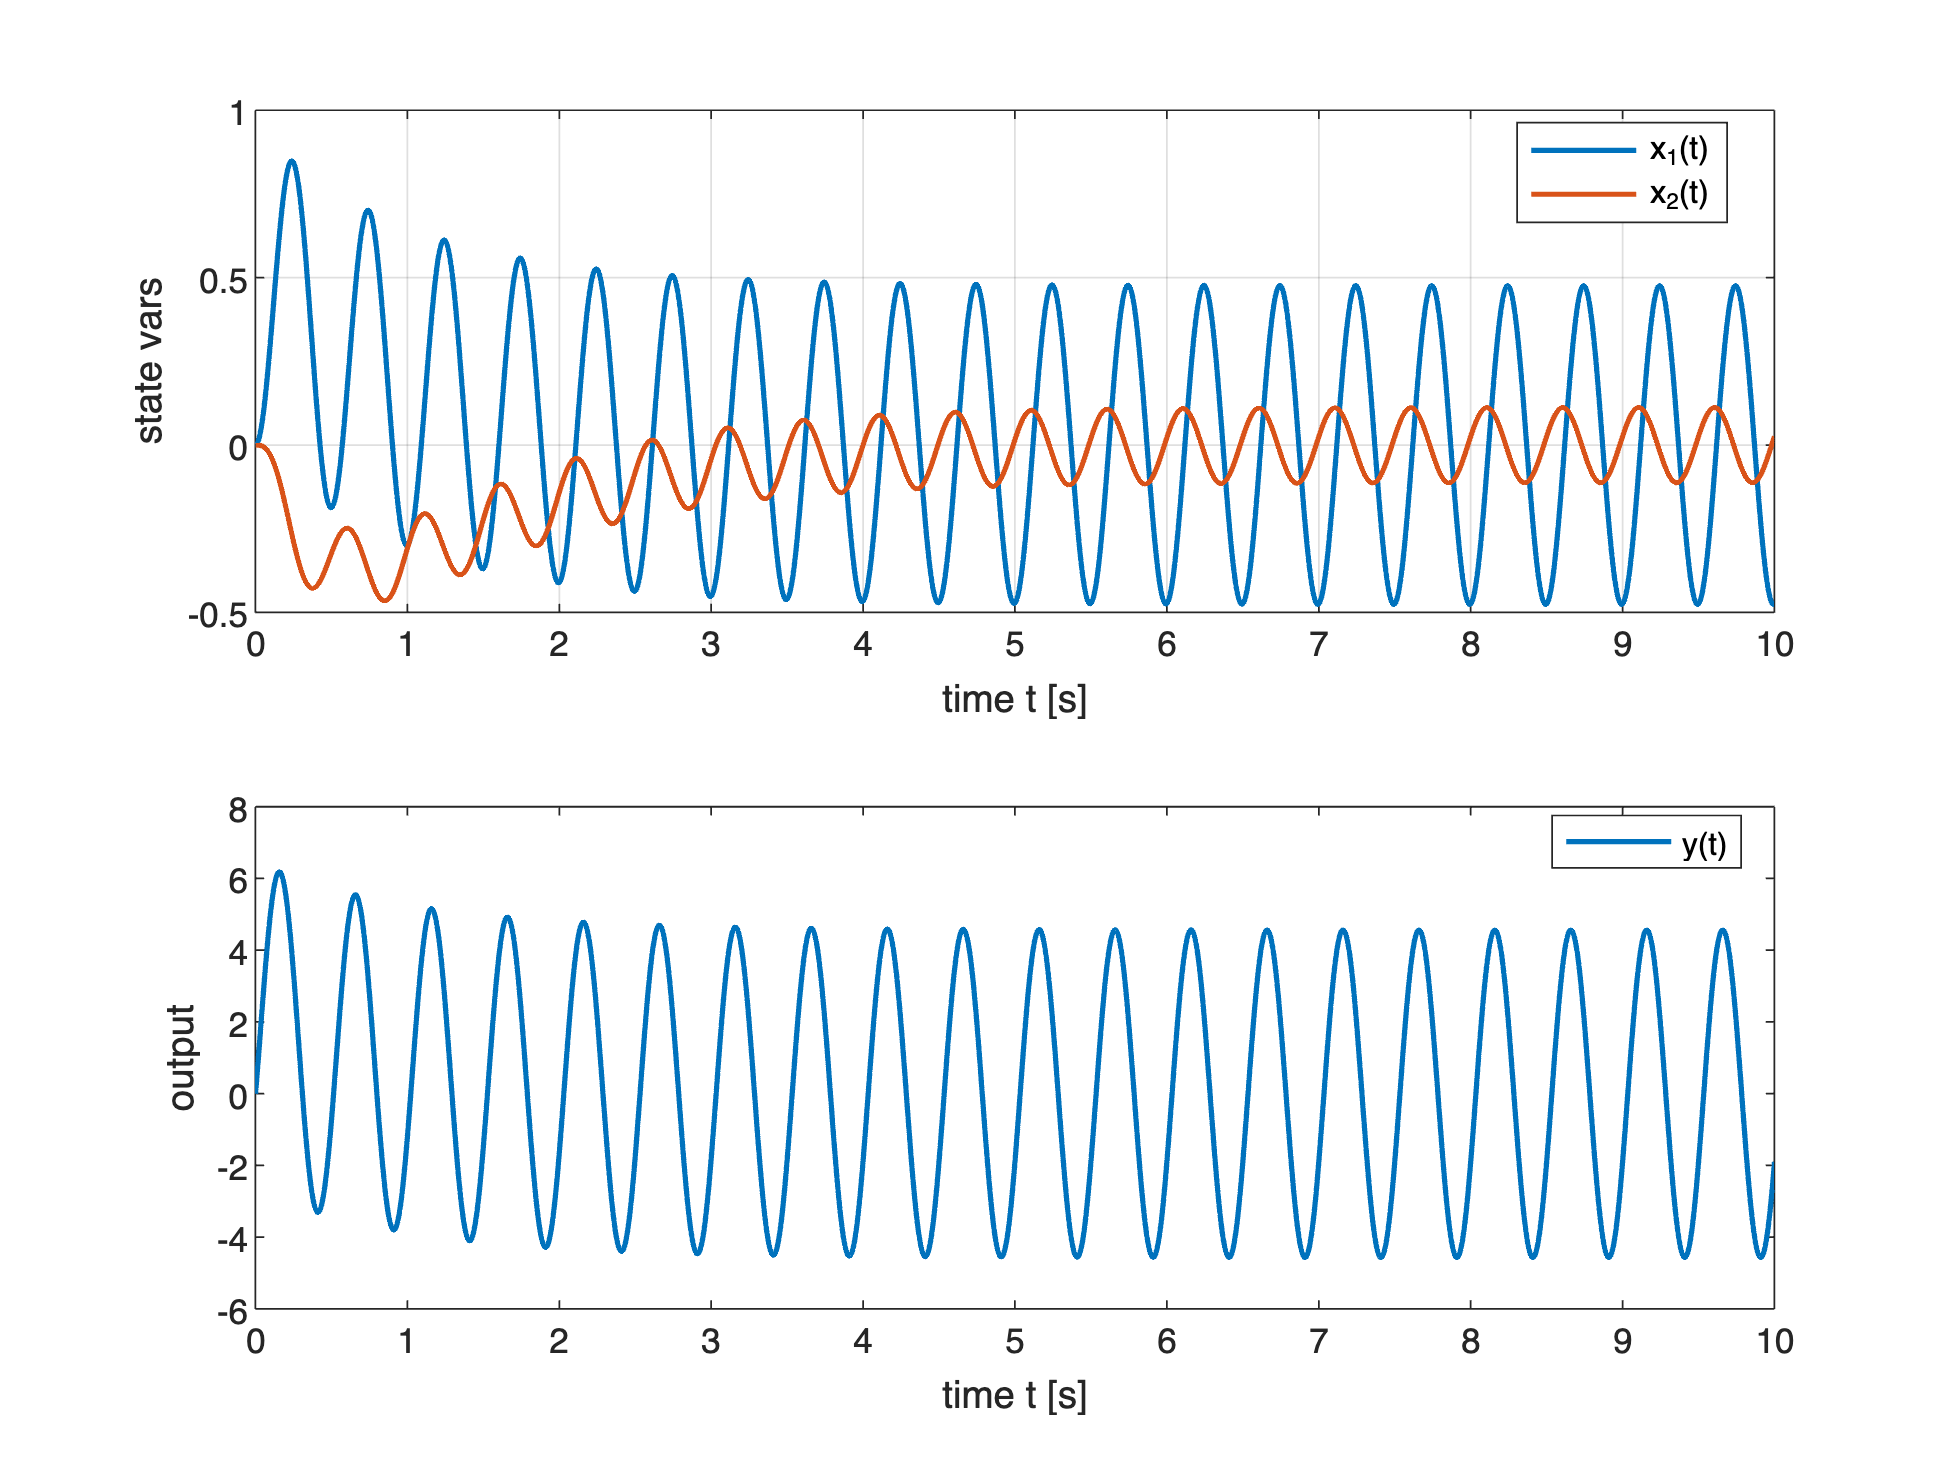


Tmax = 10; % let's simulate the system behaviour in the time interval [0, Tmax]
t = (0:0.001:Tmax); % a vector containing some time instants
u = 2*sin(2*pi*2*t); % the input values -- Notice: we do not apply the Heaviside function!

[y, ~, x] = lsim(sysC, u, t); % evaluate the forced state & output movement

figure;
subplot(2, 1, 1);
plot(t, x, 'LineWidth', 1.5);
grid on;
xlabel('time t [s]'); ylabel('state vars');
legend('x_{1}(t)', 'x_{2}(t)', 'Location', 'best')

subplot(2,1,2);
plot(t,y, 'LineWidth', 1.5); % plotting the results
xlabel('time t [s]'); ylabel('output');
legend('y(t)', 'Location', 'best')

### Example: Free Output & State Movements of a Continuous-Time System

Consider the system 


$$\left\{
\begin{array}{lcl}
\dot{x}_1(t)&=& x_2(t)\\
\dot{x}_2(t)&=&  x_3(t)\\
\dot{x}_3(t) &=& -x_1(t)-2x_2(t)-3x_3(t)+6 u(t)\\
y(t)&=&  x_1(t)
\end{array}
\right.$$


and let's evaluate the free state and output trajectories, starting from the initial state


$$x(0) = \left[ \begin{array}{c}
0 \\ -2 \\ +5
\end{array} \right]$$


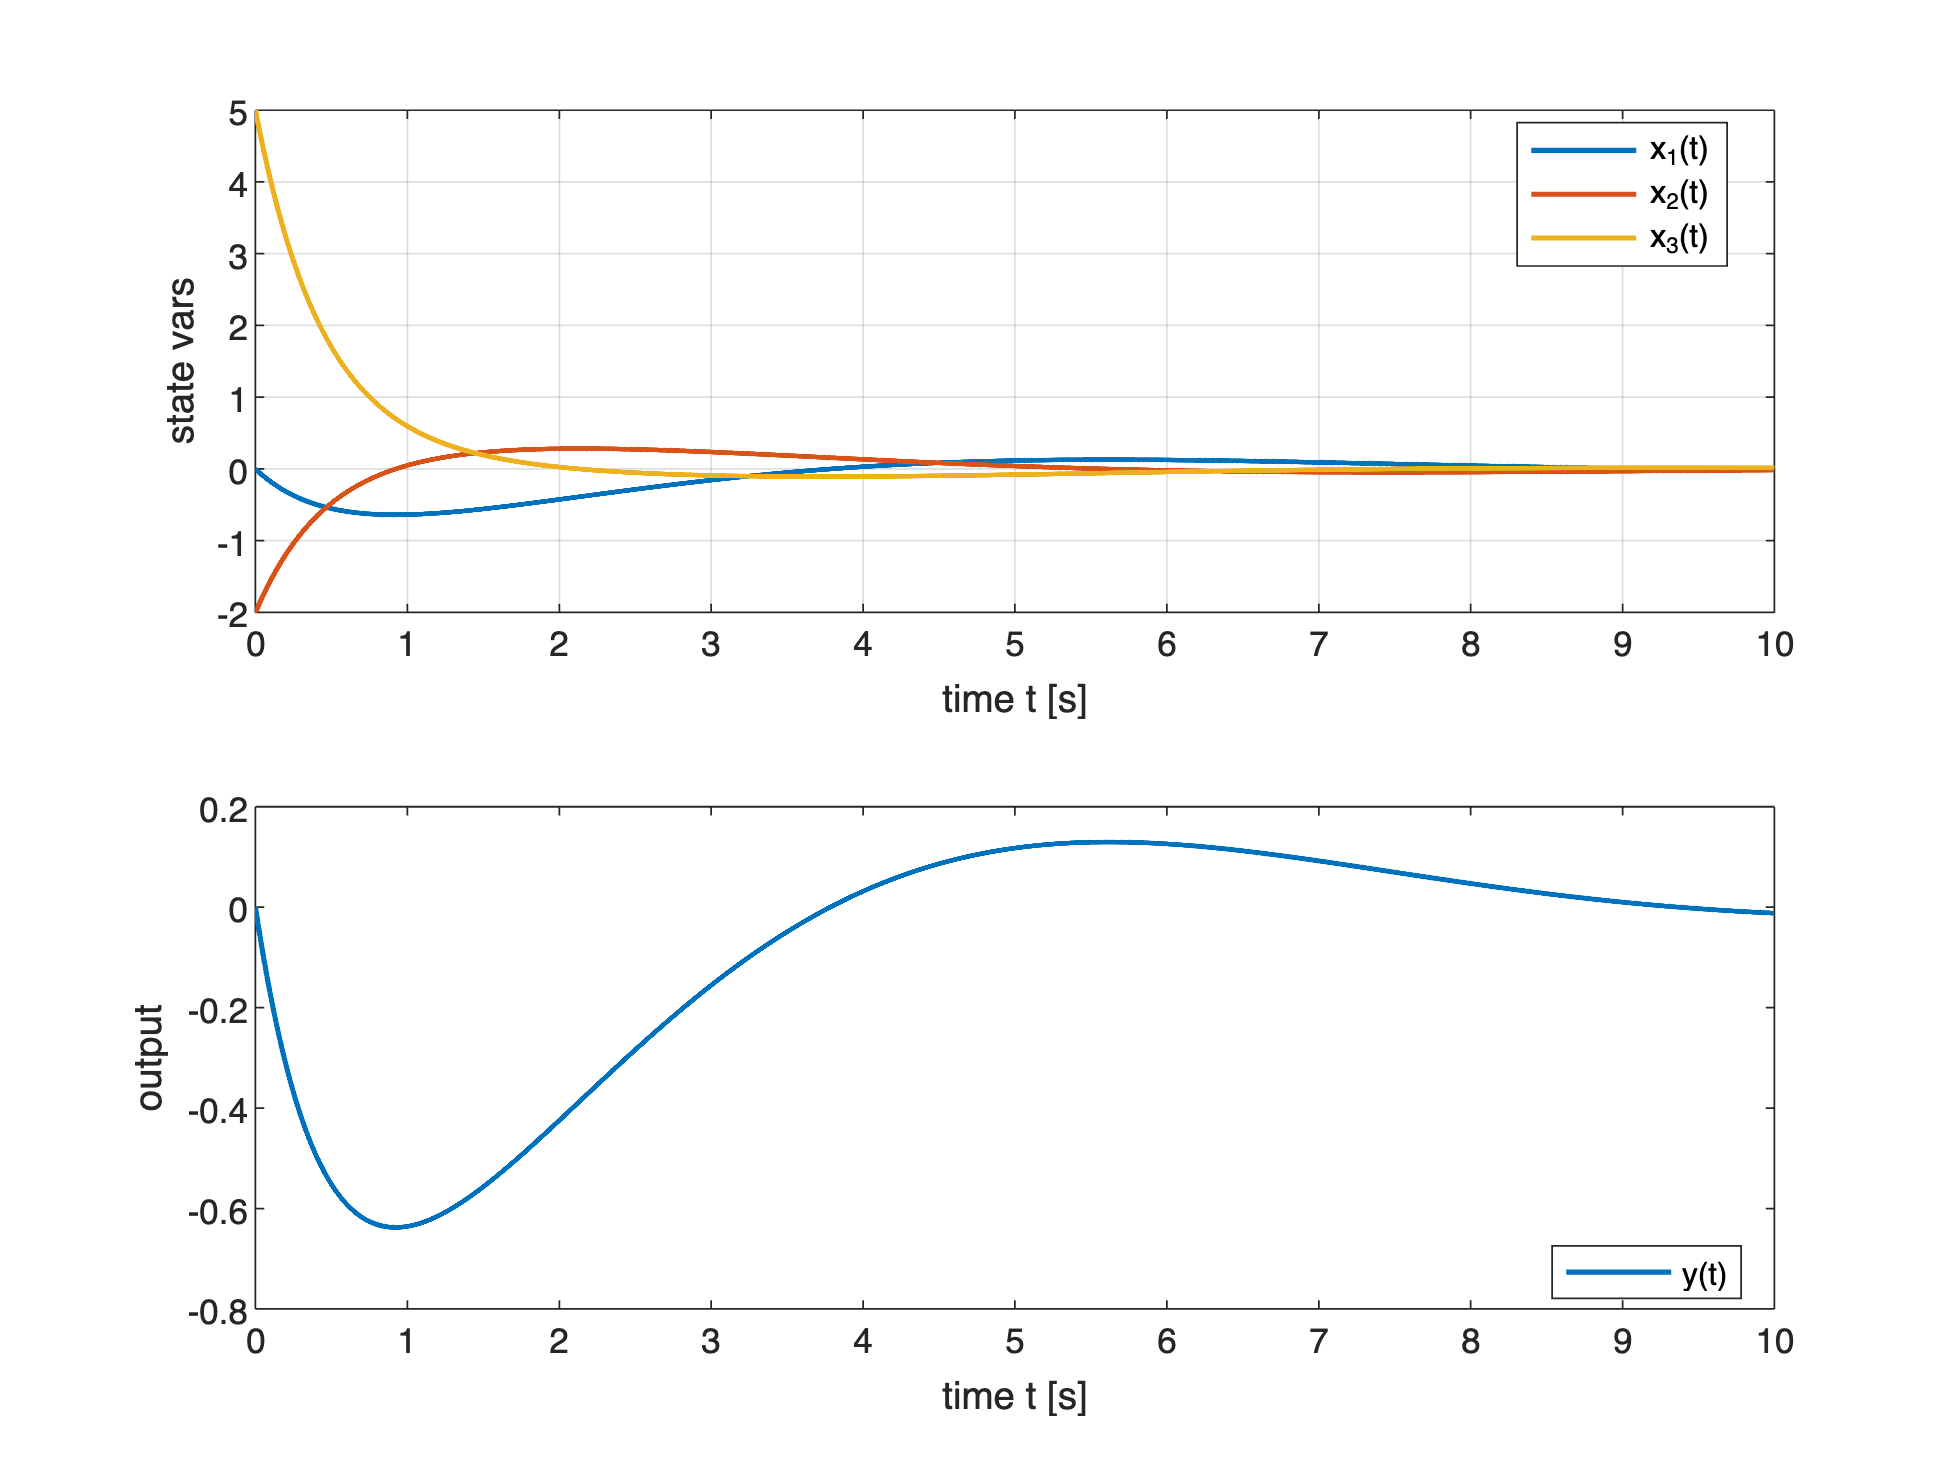

A = [0 +1 0;0  0  +1; -1  -2 -3]; B = [0; 0; 6]; C=[1  0  0]; D=0; % the system matrices
sysC_2 = ss(A, B, C, D); % the LTI system

x0 = [    0
         -2
         +5];

[y, ~, x] = initial(sysC_2, x0, t); % evaluate the forced state & output movement

figure;
subplot(2, 1, 1);
plot(t, x, 'LineWidth', 1.5);
grid on;
xlabel('time t [s]'); ylabel('state vars');
legend('x_{1}(t)', 'x_{2}(t)', 'x_{3}(t)', 'Location', 'best')

subplot(2,1,2);
plot(t,y, 'LineWidth', 1.5); % plotting the results
xlabel('time t [s]'); ylabel('output');
legend('y(t)', 'Location', 'best')

### Example: Output & State Movements of a Continuous-Time System

Consider the system 


$$\left\{
\begin{array}{lcl}
\dot{x}_1(t)&=& x_2(t)\\
\dot{x}_2(t)&=&  x_3(t)\\
\dot{x}_3(t) &=& -x_1(t)-2x_2(t)-3x_3(t)+6 u(t)\\
y(t)&=&  x_1(t)
\end{array}
\right.$$


and let's evaluate the state and output trajectories, starting from the initial state


$$x(0) = \left[ \begin{array}{c}
0 \\ -2 \\ +5
\end{array} \right]$$


when applying the input


$$u(t) = \big[3+2\,e^{-0.1 t}\sin\left(4 \pi\,t\right) \big] \cdot 1(t)$$


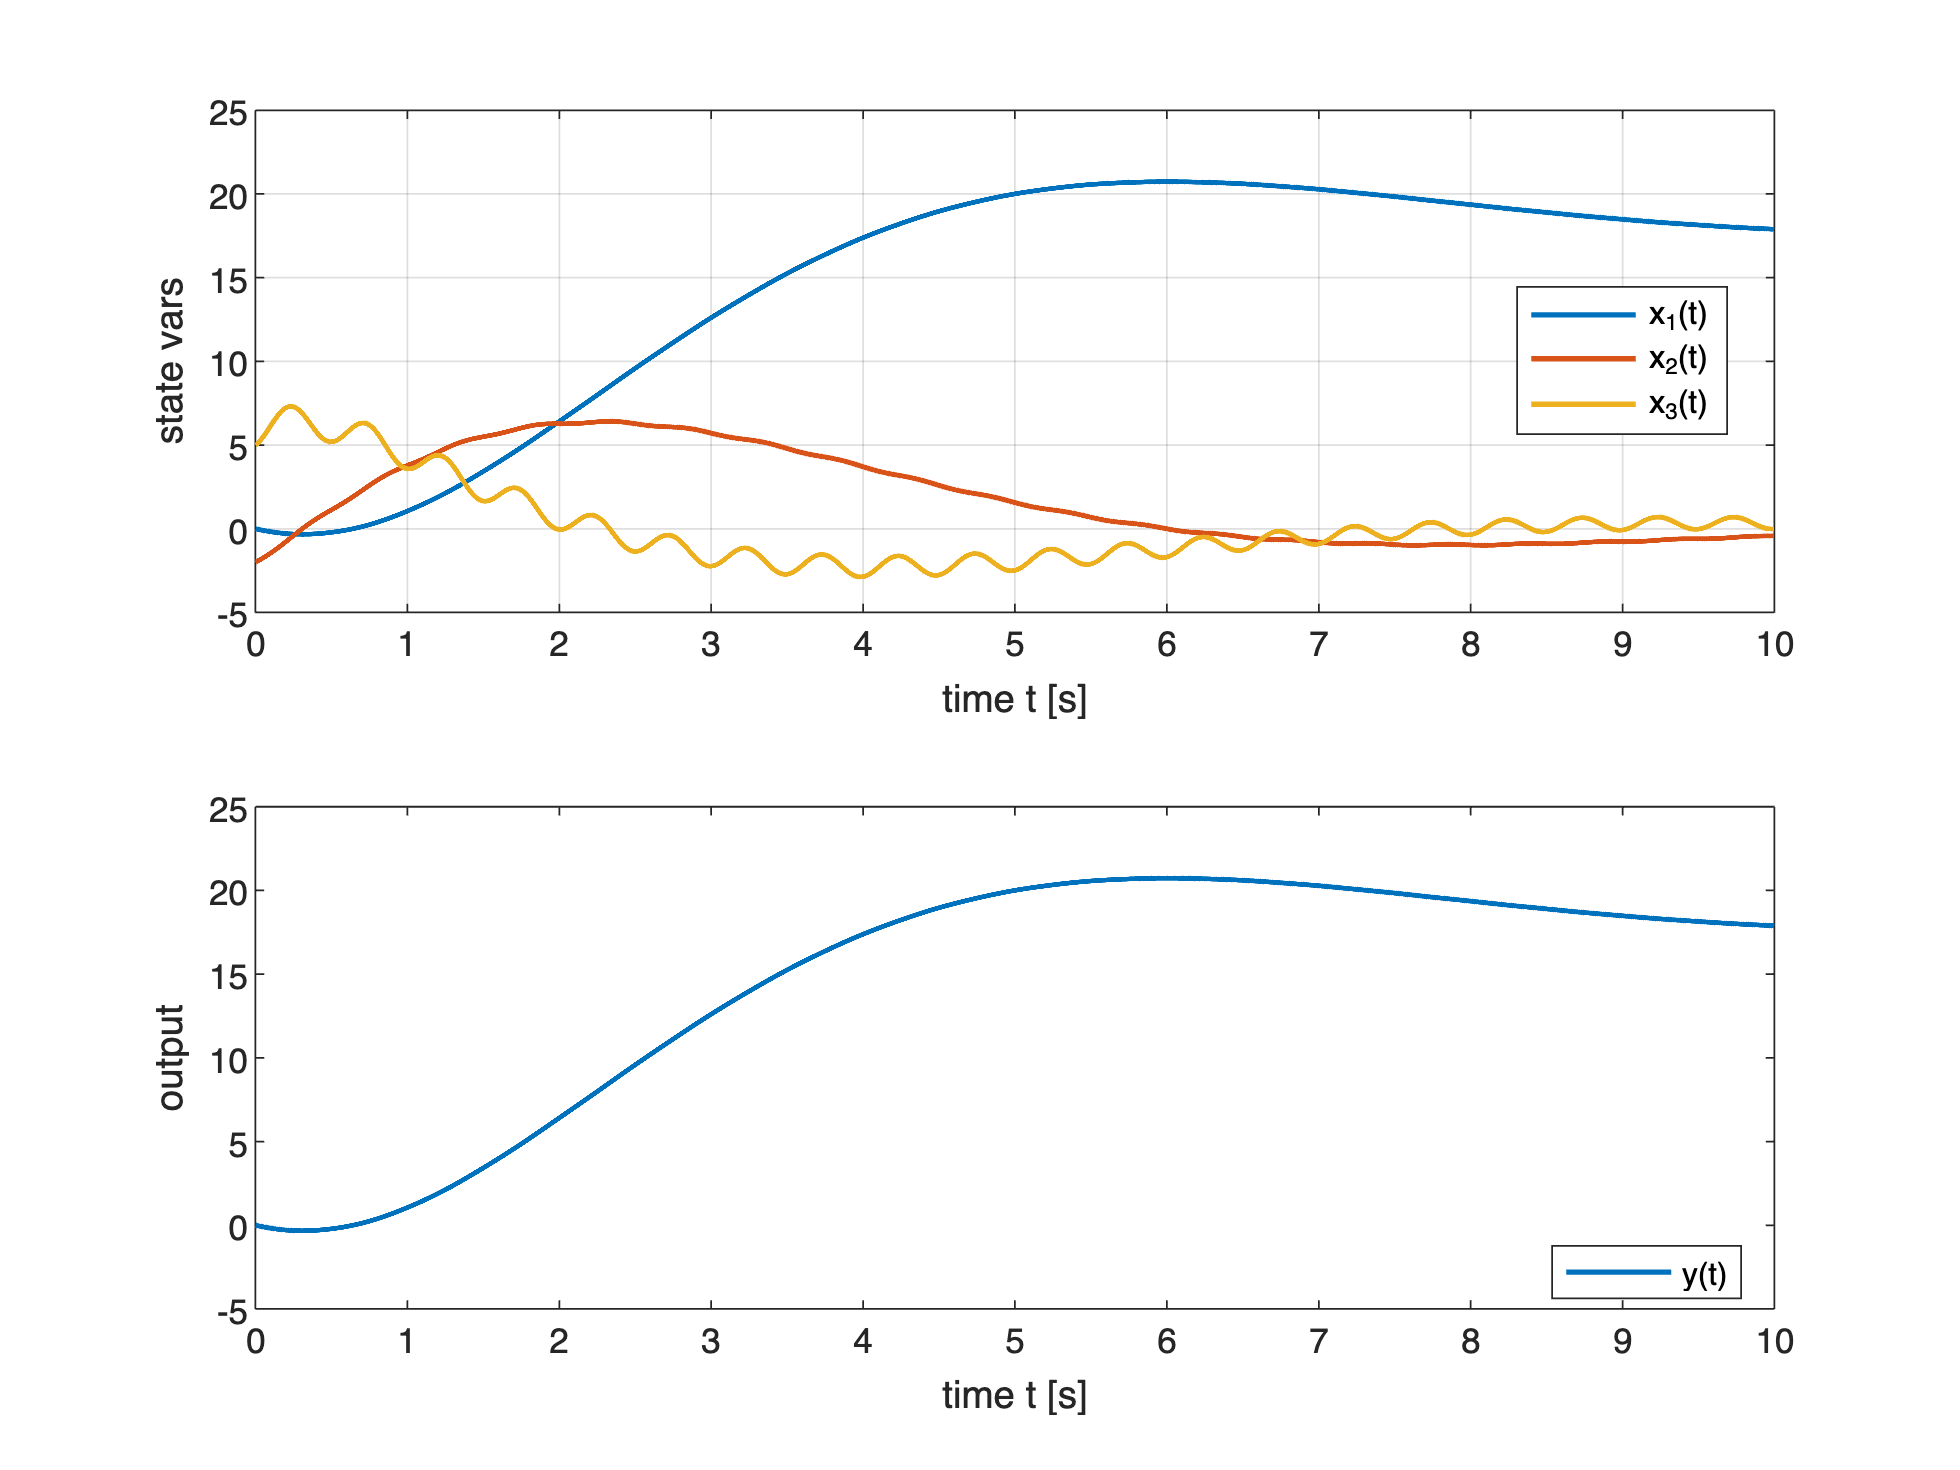

clear

A = [0 +1 0;0  0  +1; -1  -2 -3]; 
B = [0; 0; 6];
C=[1  0  0]; D=0; % the system matrices

sysC = ss(A, B, C, D); % the LTI system

x0 = [    0
         -2
         +5];

Tmax = 10; % let's simulate the system behaviour in the time interval [0, Tmax]
t = (0:0.001:Tmax); % a vector containing some time instants
u = 3+2 .* exp(-0.1*t).* sin(2*pi*2*t); % the input values -- Notice: we do not apply the Heaviside function!


% free trajs
[yfree, ~, xfree] = initial(sysC, x0, t); % evaluate the forced state & output movement

% forced trajs
[yforced, ~, xforced] = lsim(sysC, u, t); % evaluate the forced state & output movement

x = xfree + xforced;

y = yfree + yforced;

figure;
subplot(2, 1, 1);
plot(t, x, 'LineWidth', 1.5);
grid on;
xlabel('time t [s]'); ylabel('state vars');
legend('x_{1}(t)', 'x_{2}(t)', 'x_{3}(t)', 'Location', 'best')

subplot(2,1,2);
plot(t,y, 'LineWidth', 1.5); % plotting the results
xlabel('time t [s]'); ylabel('output');
legend('y(t)', 'Location', 'best')

## Summary

Using this live script you have learnt: 

- How to describe an LTI system in MATLAB;

- How to compute in MATLAB the free and the forced state and output movements for an LTI system.

#### Back to the Index

Use [this link](matlab:open('./usingMATLAB_034IN.mlx')) to go back to the main live script of the collection.

#### Back to the Previous Part: Visualisation & Programming

Use [this link](matlab:open('./Intro_MATLAB_034IN_FAC_p5.mlx')) to go back to the previous live script of this collection.